## Descrição do mecanismo

Nosso mecanismo de estudp será o braço robótico UR5e, a princípio o braço possue 6 juntas de revolução mas para fins de simplificação do sistema as juntas 1, 5 e 6 serão consideradas fixas tornan assim o problema plano

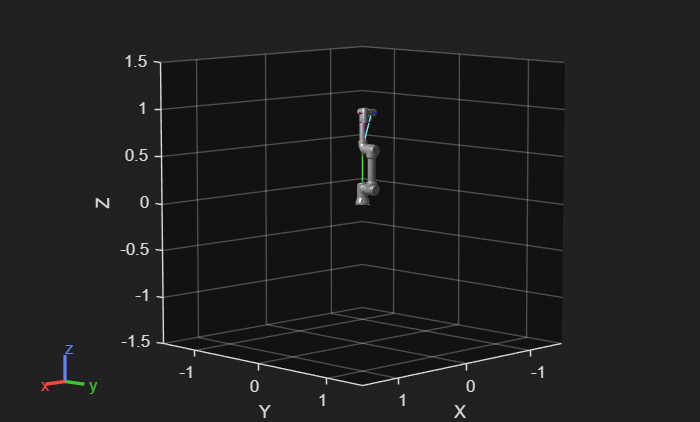

% Load the UR5e robot
UR5e = loadrobot("universalUR5e");
%load('UR5.mat');

% Get default (home) configuration for ur5e
config = homeConfiguration(UR5e);

% Modify the joint positions
config(1).JointPosition = 0;
config(2).JointPosition = -pi/2;
config(3).JointPosition = 0;
config(4).JointPosition = 0;
config(5).JointPosition = -pi/2;
config(6).JointPosition = 0;

% transformações
T_shoulder = getTransform(UR5e, config, 'shoulder_link', 'base_link_inertia');
T_wrist2   = getTransform(UR5e, config, 'wrist_2_link',  'wrist_1_link');
T_wrist3   = getTransform(UR5e, config, 'wrist_3_link',  'wrist_2_link');

% substitui 
alvos  = {'shoulder_link',      'wrist_2_link',  'wrist_3_link'};
nomes  = {'shoulder_pan_fixed', 'wrist_2_fixed', 'wrist_3_fixed'};
transf = {T_shoulder,            T_wrist2,        T_wrist3};

for k = 1:3
    novaJunta = rigidBodyJoint(nomes{k}, 'fixed');
    setFixedTransform(novaJunta, transf{k});
    replaceJoint(UR5e, alvos{k}, novaJunta);
end

% vizualização

cfg = homeConfiguration(UR5e);
for k = 1:numel(cfg)
    idx = find(strcmp({config.JointName}, cfg(k).JointName), 1);
    cfg(k).JointPosition = config(idx).JointPosition;
end

show(UR5e, cfg);

showdetails(UR5e);

--------------------
Robot: (10 bodies)

 Idx                Body Name                         Joint Name                         Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                         ----------                         ----------                ----------------   ----------------
   1                     base         base_link-base_fixed_joint                              fixed                    base_link(0)   
   2        base_link_inertia        base_link-base_link_inertia                              fixed                    base_link(0)   shoulder_link(3)  
   3            shoulder_link                 shoulder_pan_fixed                              fixed            base_link_inertia(2)   upper_arm_link(4)  
   4           upper_arm_link                shoulder_lift_joint                           revolute                shoulder_link(3)   forearm_link(5)  
   5             forearm_link                        elbow_join

## Cinemática inversa


$$q = \left[\begin{array}{c} \theta_1 \\ \theta_2 \\ \theta_3 \\ \theta_4 \\ \theta_5 \\ \theta_6 \end{array}\right]$$



$$\phi_1 = \left[\begin{array}{c} \theta_1  \\ \theta_5 + \pi/2\\ \theta_6 \end{array}\right] = 0$$



$$\phi_2 =  \theta_2 + \theta_3 + \theta_4 = 0$$



$$\phi_3 = \left[\begin{array}{c} l_2 \cos(\theta_2) + l_3 \cos(\theta_3) + l_4 \cos(\theta_4) - d_x - x \\ l_2 \sin(\theta_2) + l_3 \sin(\theta_3) + l_4 \sin(\theta_4) - d_y -y  \end{array}\right]$$


% ===== Constantes geométricas do UR5e (theta_5 = -pi/2) =====
l_2   = 0.4250;                     % a2, braço
l_3   = 0.3922;                     % a3, antebraço
l_4   = hypot(0.0996, 0.0997);      % d6 e d5 combinados = 0.14093 m
phi_4 = atan2(0.0997, -0.0996);     % fase do último elo = 134.97 deg
d_x   = 0;                          % offset horizontal da base
d_y   = 0.1625;                     % d1, altura do ombro
% plano de trabalho: y_robô = 0.1333 m (constante, fora das equações)

% ===== ALVO DO TCP - defina aqui =====
x = 0.45;
y = 0.35;

% ===== Símbolos =====
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6 real
syms dtheta_1 dtheta_2 dtheta_3 dtheta_4 dtheta_5 dtheta_6 real

q  = [theta_1; theta_2; theta_3; theta_4; theta_5; theta_6];
qd = [dtheta_1; dtheta_2; dtheta_3; dtheta_4; dtheta_5; dtheta_6];

% ===== Funções de restrição =====
phi = [ theta_1;
        theta_5 + pi/2;
        theta_6;
        theta_2 + theta_3 + theta_4 + pi/2;
        d_x +  l_2*cos(theta_2) + l_3*cos(theta_2+theta_3) + l_4*cos(theta_2+theta_3+theta_4+phi_4)  - x;
        d_y - (l_2*sin(theta_2) + l_3*sin(theta_2+theta_3) + l_4*sin(theta_2+theta_3+theta_4+phi_4)) - y ];

phi_q = jacobian(phi, q);

phi_f   = matlabFunction(phi,   'Vars', {q});
phi_q_f = matlabFunction(phi_q, 'Vars', {q});

% ===== Solução =====
chute = [0; -0.4; 1.1; -0.7; -pi/2; 0];
[q_sol, iter] = newton_raphson(phi_f, phi_q_f, chute, 1e-12, 80)

q_sol =          0
   -1.6108
    1.9691
   -1.9292
   -1.5708
         0


iter = 7

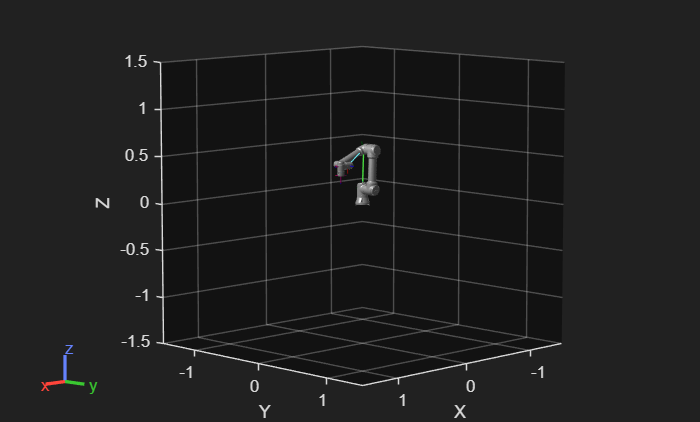


cfg = homeConfiguration(UR5e);      % 3 GDL: shoulder_lift, elbow, wrist_1
cfg(1).JointPosition = q_sol(2);    % theta_2
cfg(2).JointPosition = q_sol(3);    % theta_3
cfg(3).JointPosition = q_sol(4);    % theta_4

show(UR5e, cfg, 'Frames', 'on');

## Funções

function [q, iter] = newton_raphson(f, df, chute, tol, n)
    q = chute;
    for iter = 1:n
        F = f(q);
        J = df(q);
        dq = -(J \ F);
        q  = q + dq;
        if norm(F) < tol && norm(dq) < tol
            return
        end
    end
end